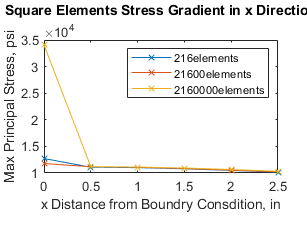

clear;close;clc;

%dont use the first 6

load('rect_1_stress.mat')
stress1 = stress;
clear stress

load('rect_2_stress_10spaced.mat')
stress2 = stress;
clear stress

load('rect_3_stress_100space.mat')
stress3 = stress;
clear stress

stresses = [stress1,stress2,stress3];
dist = [0:5]*.5;

figure;
plot(dist,stresses,'x-');
legend 216elements 21600elements 2160000elements; hold on;
ylabel('Max Principal Stress, psi');
xlabel({'x Distance from Boundry Consdition, in',''});
title({'Square Elements Stress Gradient in x Direction',''});

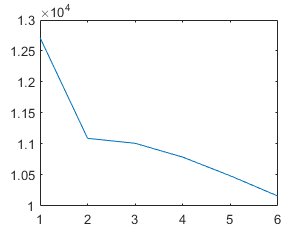

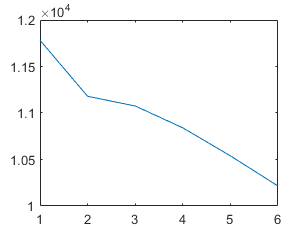

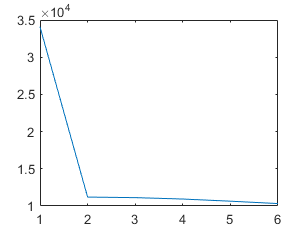



for i = 1:size(stresses,2)
    figure;
    plot(stresses(:,i))
end



load('rect_2_stress_10spaced.mat')
stress2_close = stress;
clear stress

load('rect_3_stress_100space.mat')
stress3_close = stress;
clear stress

stressesClose = [stress1,stress2_close,stress3_close];
for i = 1:size(stressesClose,2)
    figure;
    plot(stressesClose(:,i))
end

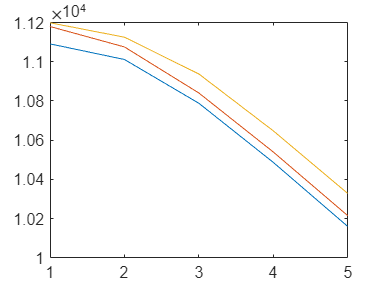




plot(rmoutliers(stresses))

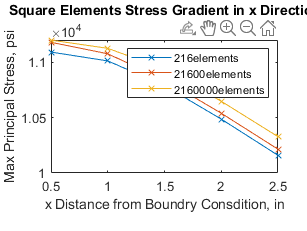


plot(dist(2:6),stresses(2:6,:),"x-")
legend 216elements 21600elements 2160000elements;
ylabel('Max Principal Stress, psi');
xlabel({'x Distance from Boundry Consdition, in',''});
title({'Square Elements Stress Gradient in x Direction',''});


plot(dist(3:6),stresses(3:6,:),"x")
legend 216elements 21600elements 2160000elements;
hold on;


stressFit1 = fit(dist(3:6)',stresses(3:6,1),"poly1")

stressFit1 =      Linear model Poly1:
     stressFit1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -571.4  (-715.7, -427.1)
       p2 =   1.161e+04  (1.135e+04, 1.188e+04)

stressFit2 = fit(dist(3:6)',stresses(3:6,2),"poly1")

stressFit2 =      Linear model Poly1:
     stressFit2(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -576.7  (-701.5, -451.9)
       p2 =   1.168e+04  (1.145e+04, 1.191e+04)

stressFit3 = fit(dist(3:6)',stresses(3:6,3),"poly1")

stressFit3 =      Linear model Poly1:
     stressFit3(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -536.3  (-721.1, -351.5)
       p2 =    1.17e+04  (1.136e+04, 1.204e+04)

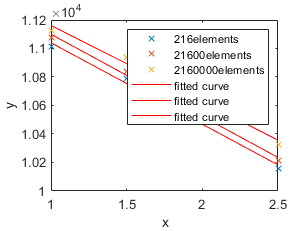


plot(stressFit1)
plot(stressFit2)
plot(stressFit3)

stressFit1(0)

ans = 1.1611e+04

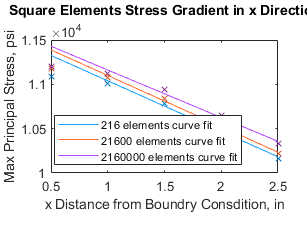


stressFitPoints = zeros(size(stresses));
for i = 1:size(stresses,1)
    stressFitPoints(i,1) = stressFit1(dist(i));
    stressFitPoints(i,2) = stressFit2(dist(i));
    stressFitPoints(i,3) = stressFit3(dist(i));
end

HW_11_Rect_GradientPlot(dist(2:6),stresses(2:6,:),stressFit1,stressFit2,stressFit3)

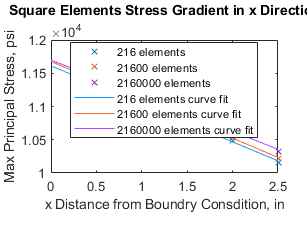

HW_11_Rect_GradientPlot2(dist(2:6),stresses(2:6,:),dist,stressFitPoints)

## Convergence

%nodes = [259,22021,2164201]; % this is defined from f06 file
meshSeedSize = [.5,.05,.005];
elements = (18./meshSeedSize) .* (3./meshSeedSize);
nodes = (18./meshSeedSize+1) .* (3./meshSeedSize+1);
constrainedNodes = 3./meshSeedSize;
degFreePerNode = 3;
degFree = (nodes-constrainedNodes)*degFreePerNode

degFree =          759       65883     6490803



myfittype = fittype('b*(x-a)/(x-c)',...
    'dependent',{'y'},'independent',{'x'},...
    'coefficients',{'a','b','c'})

myfittype =      General model:
     myfittype(a,b,c,x) = b*(x-a)/(x-c)

myfit = fit(degFree',stressFitPoints(1,:)',myfittype)

myfit =      General model:
     myfit(x) = b*(x-a)/(x-c)
     Coefficients:
       a =  -2.066e+04
       b =    1.17e+04
       c =  -2.082e+04

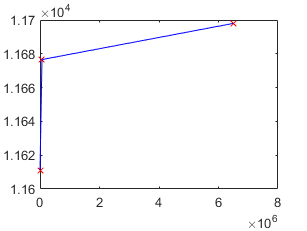


figure;
plot(degFree,stressFitPoints(1,:),'xr');hold on;
plot(degFree,stressFitPoints(1,:),'-b');

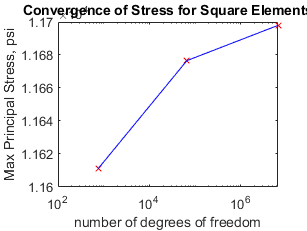

%plot(myfit,'.g')
figure;

semilogx(degFree,stressFitPoints(1,:),'xr'); hold on;
semilogx(degFree,stressFitPoints(1,:),'-b');
%plot(myfit,'.g')
ylabel("Max Principal Stress, psi");
xlabel("number of degrees of freedom");
title("Convergence of Stress for Square Elements")


stressFitPoints(1,:)

ans = 1.0e+04 *

    1.1611    1.1677    1.1698
